clear;
disp('~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~')

~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~


disp('Energy Efficient (EE) Motor parameters')

Energy Efficient (EE) Motor parameters


disp('~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~')

~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~


 
f=50;                    %Supply frequency [Hz]
p=4;                     %Number of poles
V1=380/sqrt(3);          %Supply voltage [phase]
R1_ee = 1.5;             %Stator winding resistance [ohms/phase]
X1_ee = 3.642;           %Stator winding leakage reactance [ohms/phase]
Xm_ee = 72.252;          %Stator winding magnetising reactance [ohms/phase]
X2p_ee = 3.642;          %Rotor winding leakage reactance reffered to stator [ohms/phase]
R2p_ee = 1.994;          %Rotor winding resistance reffered to stator [ohms/phase]

fprintf('f=%f\n',f);

f=50.000000


fprintf('p=%f\n',p);

p=4.000000


fprintf('V1=%f\n',V1);

V1=219.393102


fprintf('R1_ee=%f\n',R1_ee);

R1_ee=1.500000


fprintf('X1_ee=%f\n',X1_ee);

X1_ee=3.642000


fprintf('Xm_ee=%f\n',Xm_ee);

Xm_ee=72.252000


fprintf('X2p_ee=%f\n',X2p_ee);

X2p_ee=3.642000


fprintf('R2p_ee=%f\n',R2p_ee);

R2p_ee=1.994000


disp('~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~')

~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~


disp('Standard Efficiency (SE) Motor parameters')

Standard Efficiency (SE) Motor parameters


disp('~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~')

~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~



R1_se = 2.087;           %Stator winding resistance [ohms/phase]
X1_se = 4.274;           %Stator winding leakage reactance [ohms/phase]
Xm_se = 66.560;          %Stator winding magnetising reactance [ohms/phase]
X2p_se = 4.274;          %Rotor winding leakage reactance reffered to stator [ohms/phase]
R2p_se = 2.122;          %Rotor winding resistance reffered to stator [ohms/phase]

fprintf('f=%f\n',f);

f=50.000000


fprintf('p=%f\n',p);

p=4.000000


fprintf('V1=%f\n',V1);

V1=219.393102


fprintf('R1_se=%f\n',R1_se);

R1_se=2.087000


fprintf('X1_se=%f\n',X1_se);

X1_se=4.274000


fprintf('Xm_se=%f\n',Xm_se);

Xm_se=66.560000


fprintf('X2p_se=%f\n',X2p_se);

X2p_se=4.274000


fprintf('R2p_se=%f\n',R2p_se);

R2p_se=2.122000


disp('~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~')

~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~


disp('Question 1: Thevenin Equiv Cct Parameters for EE Motor:')

Question 1: Thevenin Equiv Cct Parameters for EE Motor:


disp('~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~')

~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~



Vth_ee=Xm_ee/sqrt(R1_ee^2+(X1_ee+Xm_ee)^2)*V1;         %Thevenin equiv voltage source [V] (Equ 5.45 - Sen)
Zth_ee=1i*Xm_ee*(R1_ee+1i*X1_ee)/(R1_ee+1i*(X1_ee+Xm_ee));   %Thevenin equiv impedance
Rth_ee=real(Zth_ee);                          %Thevenin equiv resistance [ohms]
Xth_ee=imag(Zth_ee);                          %Thevenin equiv reactance [ohms]


fprintf('Vth=%f\n',Vth_ee);

Vth=208.824087


fprintf('Rth=%f\n',Rth_ee);

Rth=1.358959


fprintf('Xth=%f\n',Xth_ee);

Xth=3.494087



disp('~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~')

~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~


disp('Question 1: Thevenin Equiv Cct Parameters for SE Motor:')

Question 1: Thevenin Equiv Cct Parameters for SE Motor:


disp('~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~')

~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~



Vth_se=Xm_se/sqrt(R1_se^2+(X1_se+Xm_se)^2)*V1;         %Thevenin equiv voltage source [V] (Equ 5.45 - Sen)
Zth_se=1i*Xm_se*(R1_se+1i*X1_ee)/(R1_se+1i*(X1_se+Xm_se));   %Thevenin equiv impedance
Rth_se=real(Zth_se);                          %Thevenin equiv resistance [ohms]
Xth_se=imag(Zth_se);                          %Thevenin equiv reactance [ohms]


fprintf('Vth=%f\n',Vth_se);

Vth=206.065883


fprintf('Rth=%f\n',Rth_se);

Rth=1.858630


fprintf('Xth=%f\n',Xth_se);

Xth=3.477009


disp('~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~')

~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~


disp('QUESTION 2:Torque versus speed characteristics for EE Motor:')

QUESTION 2:Torque versus speed characteristics for EE Motor:


disp('~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~')

~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~


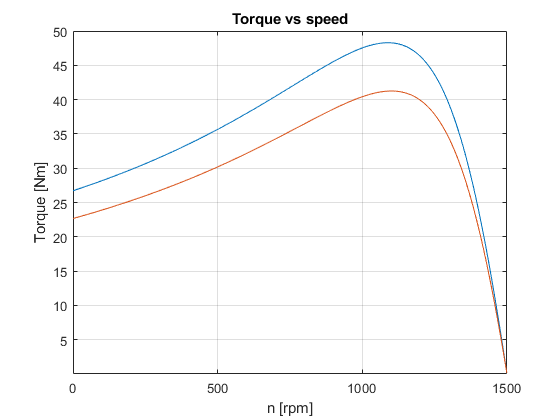


ns=120*f/p;         %Synchronous speed [rpm]
ws=2*pi*ns/60;      %Synchronous speed [rad/sec]
s=0.0005:0.0005:1;  %Slip [pu]
n=(1-s)*ns;         %Rotor speed [rpm]
w=2*pi*n/60;        %Rotor speed [rad/sec]
 

% Torque calculation for EE motor
Tmech_ee = 3/ws*Vth_ee^2./((Rth_ee+R2p_ee./s).^2+(Xth_ee+X2p_ee)^2).*R2p_ee./s;    %Total Tmech = {3*(Equ5.54 - Sen)}

% Torque calculation for SE motor
Tmech_se = 3/ws*Vth_se^2./((Rth_se+R2p_se./s).^2+(Xth_se+X2p_se)^2).*R2p_se./s;

%Plot the Torque vs speed characteristics of both motors on same plot:
%subplot(2,2,1),
plot(n,Tmech_ee),xlabel('n [rpm]'),ylabel('Torque [Nm]'),...
    title('Torque vs speed'),grid on,...
    hold on
plot(n,Tmech_se)

hold off

% Calculate starting torque of machines
disp('(a) Starting Torque')

(a) Starting Torque



% Starting torque of EE motor
Tstart_ee = 3/ws*Vth_ee^2/((Rth_ee+R2p_ee/1)^2+(Xth_ee+X2p_ee)^2)*R2p_ee/1;    % Tstart = Tmech @ s = 1

% Starting torque of SE motor
Tstart_se = 3/ws*Vth_se^2/((Rth_se+R2p_se/1)^2+(Xth_se+X2p_se)^2)*R2p_se/1;

fprintf('Starting torque of EE motor = %f N.m\n',Tstart_ee);

Starting torque of EE motor = 26.713715 N.m


fprintf('Starting torque of SE motor = %f N.m\n',Tstart_se);

Starting torque of SE motor = 22.666391 N.m



disp(['The starting torque can be increased by increasing the rotor resistance, and' ...
    ' decreased by decreasing the rotor resistance.'])

The starting torque can be increased by increasing the rotor resistance, and decreased by decreasing the rotor resistance.


% Calculate maximum (breakdown) torques of machines
disp('(b) Maximum Torque')

(b) Maximum Torque



% Maximum torque of EE motor
Tmax_ee = 3/(2*ws)*Vth_ee^2/( Rth_ee + sqrt(Rth_ee^2 + (Xth_ee+X2p_ee)^2) )

Tmax_ee = 48.2903


% Maximum torque of SE motor
Tmax_se = 3/(2*ws)*Vth_se^2/( Rth_se + sqrt(Rth_se^2 + (Xth_se+X2p_se)^2) )

Tmax_se = 41.2532


fprintf('Maximum torque of EE motor = %f N.m\n',Tstart_ee);

Maximum torque of EE motor = 26.713715 N.m


fprintf('Maximum torque of SE motor = %f N.m\n',Tstart_se);

Maximum torque of SE motor = 22.666391 N.m



disp(['The maximum torque is dependent of the the Thevenin equivalent voltage Vth. Thus, the maximum torque can ' ...
    'be increased by increasing Vth and decreased by decreasing Vth'])

The maximum torque is dependent of the the Thevenin equivalent voltage Vth. Thus, the maximum torque can be increased by increasing Vth and decreased by decreasing Vth


% Caculate speed (in rpm) at which maximum torque occurs for the machines
disp('(c) Speed at maximum torque');

(c) Speed at maximum torque



% EE motor
s_Tmax_ee = R2p_ee/sqrt(Rth_ee^2 + (Xth_ee + X2p_ee)^2)

s_Tmax_ee = 0.2745

n_Tmax_ee = ns*(1-s_Tmax_ee)

n_Tmax_ee = 1.0883e+03


% SE motor
s_Tmax_se = R2p_se/sqrt(Rth_se^2 + (Xth_se + X2p_se)^2)

s_Tmax_se = 0.2662

n_Tmax_se = ns*(1-s_Tmax_se)

n_Tmax_se = 1.1007e+03


fprintf('Speed at maximum torque of EE motor = %f rpm\n',n_Tmax_ee);

Speed at maximum torque of EE motor = 1088.262157 rpm


fprintf('Speed at maximum torque of SE motor = %f rpm\n',n_Tmax_se);

Speed at maximum torque of SE motor = 1100.664291 rpm


% Stator current vs. speed characteristics of machines

% EE motor
Z1_ee = R1_ee + 1i*X1_ee + 1i*Xm_ee*(R2p_ee./s+1i*X2p_ee)./(R2p_ee./s+1i*(Xm_ee+X2p_ee))

Z1_ee =    2.8085 +75.8691i   4.1142 +75.7945i   5.4143 +75.6705i   6.7059 +75.4977i   7.9863 +75.2768i   9.2530 +75.0087i  10.5033 +74.6946i  11.7349 +74.3358i  12.9454 +73.9337i  14.1326 +73.4899i  15.2947 +73.0063i  16.4296 +72.4846i  17.5357 +71.9268i  18.6116 +71.3350i  19.6558 +70.7113i  20.6672 +70.0578i  21.6448 +69.3768i  22.5878 +68.6704i  23.4956 +67.9408i  24.3676 +67.1903i  25.2035 +66.4211i  26.0032 +65.6352i  26.7666 +64.8347i  27.4939 +64.0217i  28.1851 +63.1982i  28.8408 +62.3659i  29.4612 +61.5268i  30.0469 +60.6826i  30.5986 +59.8349i  31.1169 +58.9852i  31.6026 +58.1350i  32.0565 +57.2858i  32.4794 +56.4387i  32.8722 +55.5949i  33.2359 +54.7557i  33.5714 +53.9218i  33.8797 +53.0944i  34.1617 +52.2743i  34.4184 +51.4622i  34.6509 +50.6587i  34.8601 +49.8646i  35.0469 +49.0804i  35.2124 +48.3066i  35.3575 +47.5435i  35.4831 +46.7917i  35.5901 +46.0513i  35.6795 +45.3226i  35.7520 +44.6059i  35.8086 +43.9013i  35.8500 +43.2090i


I1_ee = V1./Z1_ee

I1_ee =    0.1069 - 2.8878i   0.1567 - 2.8861i   0.2064 - 2.8846i   0.2561 - 2.8832i   0.3058 - 2.8820i   0.3554 - 2.8811i   0.4050 - 2.8802i   0.4546 - 2.8796i   0.5041 - 2.8792i   0.5536 - 2.8789i   0.6031 - 2.8788i   0.6525 - 2.8789i   0.7019 - 2.8791i   0.7513 - 2.8795i   0.8006 - 2.8801i   0.8499 - 2.8809i   0.8991 - 2.8818i   0.9483 - 2.8830i   0.9974 - 2.8842i   1.0465 - 2.8857i   1.0956 - 2.8873i   1.1446 - 2.8891i   1.1936 - 2.8911i   1.2425 - 2.8933i   1.2914 - 2.8956i   1.3402 - 2.8981i   1.3890 - 2.9007i   1.4377 - 2.9036i   1.4864 - 2.9065i   1.5350 - 2.9097i   1.5835 - 2.9130i   1.6321 - 2.9165i   1.6805 - 2.9202i   1.7289 - 2.9240i   1.7773 - 2.9280i   1.8255 - 2.9322i   1.8738 - 2.9365i   1.9219 - 2.9410i   1.9701 - 2.9456i   2.0181 - 2.9504i   2.0661 - 2.9554i   2.1140 - 2.9605i   2.1619 - 2.9658i   2.2097 - 2.9713i   2.2574 - 2.9769i   2.3051 - 2.9826i   2.3527 - 2.9886i   2.4002 - 2.9947i   2.4477 - 3.0009i   2.4951 - 3.0073i



% SE motor
Z1_se = R1_se +  1i*X1_se + 1i*Xm_se*(R2p_se./s+1i*X2p_se)./(R2p_se./s+1i*(Xm_se+X2p_se))

Z1_se =    3.1306 +70.8166i   4.1724 +70.7644i   5.2108 +70.6776i   6.2440 +70.5565i   7.2703 +70.4014i   8.2881 +70.2130i   9.2958 +69.9918i  10.2918 +69.7385i  11.2746 +69.4539i  12.2429 +69.1389i  13.1953 +68.7946i  14.1305 +68.4219i  15.0473 +68.0219i  15.9447 +67.5959i  16.8217 +67.1451i  17.6773 +66.6707i  18.5108 +66.1740i  19.3214 +65.6563i  20.1085 +65.1191i  20.8715 +64.5636i  21.6101 +63.9912i  22.3239 +63.4032i  23.0126 +62.8011i  23.6761 +62.1861i  24.3142 +61.5595i  24.9269 +60.9226i  25.5143 +60.2767i  26.0764 +59.6230i  26.6136 +58.9626i  27.1259 +58.2967i  27.6137 +57.6264i  28.0773 +56.9528i  28.5172 +56.2767i  28.9337 +55.5992i  29.3272 +54.9213i  29.6983 +54.2436i  30.0476 +53.5671i  30.3754 +52.8925i  30.6824 +52.2205i  30.9692 +51.5518i  31.2363 +50.8870i  31.4843 +50.2266i  31.7139 +49.5712i  31.9256 +48.9212i  32.1200 +48.2772i  32.2978 +47.6395i  32.4595 +47.0084i  32.6057 +46.3843i  32.7371 +45.7675i  32.8541 +45.1582i


I1_se = V1./Z1_se

I1_se =    0.1367 - 3.0920i   0.1822 - 3.0896i   0.2276 - 3.0874i   0.2730 - 3.0853i   0.3184 - 3.0834i   0.3638 - 3.0817i   0.4091 - 3.0802i   0.4544 - 3.0789i   0.4996 - 3.0777i   0.5448 - 3.0767i   0.5900 - 3.0759i   0.6351 - 3.0753i   0.6802 - 3.0749i   0.7252 - 3.0746i   0.7702 - 3.0745i   0.8152 - 3.0746i   0.8601 - 3.0748i   0.9050 - 3.0752i   0.9498 - 3.0758i   0.9946 - 3.0766i   1.0393 - 3.0775i   1.0840 - 3.0786i   1.1286 - 3.0799i   1.1732 - 3.0814i   1.2177 - 3.0830i   1.2621 - 3.0848i   1.3066 - 3.0867i   1.3509 - 3.0888i   1.3952 - 3.0911i   1.4395 - 3.0936i   1.4837 - 3.0962i   1.5278 - 3.0990i   1.5719 - 3.1020i   1.6159 - 3.1051i   1.6598 - 3.1084i   1.7037 - 3.1118i   1.7475 - 3.1154i   1.7913 - 3.1192i   1.8350 - 3.1231i   1.8786 - 3.1272i   1.9222 - 3.1315i   1.9657 - 3.1359i   2.0091 - 3.1404i   2.0525 - 3.1452i   2.0958 - 3.1501i   2.1390 - 3.1551i   2.1822 - 3.1603i   2.2253 - 3.1656i   2.2683 - 3.1712i   2.3112 - 3.1768i


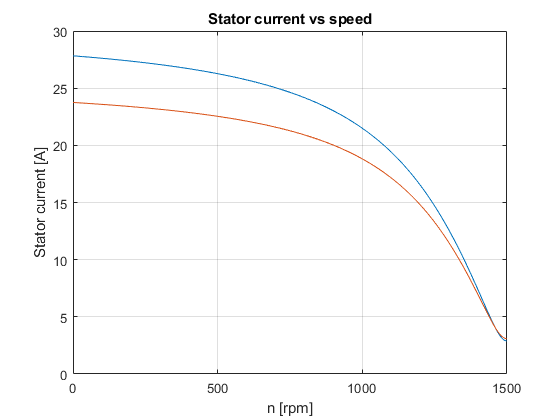


% Plot stator current vs. speed characteristic curves
plot(n,abs(I1_ee)),xlabel('n [rpm]'),ylabel('Stator current [A]'),...
    title('Stator current vs speed'),grid on,...
    hold on
plot(n,abs(I1_se))

hold off

% (a) Stator current at startup
disp('(a) Stator current at startup')

(a) Stator current at startup



% EE motor
fprintf('Stator current of Energy Efficient machine at startup = %f A',abs(I1_ee(2000)))

Stator current of Energy Efficient machine at startup = 27.829877 A


% SE motor
fprintf('Stator current of Standard machine at startup = %f A',abs(I1_se(2000)))

Stator current of Standard machine at startup = 23.750131 A

% (c) Stator currents when the machines develop maximum torque
disp('(c) Stator currents when the machines develop maximum torque')

(c) Stator currents when the machines develop maximum torque



% EE motor
Z1_sTmax_ee = R1_ee + 1i*X1_ee + 1i*Xm_ee*(R2p_ee/s_Tmax_ee+1i*X2p_ee)/(R2p_ee/s_Tmax_ee+1i*(Xm_ee+X2p_ee))

Z1_sTmax_ee = 8.0241 + 7.7337i

I1_sTmax_ee = V1/Z1_sTmax_ee

I1_sTmax_ee = 14.1746 - 13.6616i

fprintf('Stator current of Energy Efficient machine at max torque = %f A',abs(I1_sTmax_ee))

Stator current of Energy Efficient machine at max torque = 19.686532 A


% SE motor
Z1_sTmax_se = R1_se + 1i*X1_se + 1i*Xm_se*(R2p_se/s_Tmax_se+1i*X2p_se)/(R2p_se/s_Tmax_se+1i*(Xm_se+X2p_se))

Z1_sTmax_se = 9.0369 + 9.0722i

I1_sTmax_se = V1/Z1_sTmax_se

I1_sTmax_se = 12.0915 - 12.1387i

fprintf('Stator current of Standard machine at max torque = %f A',abs(I1_sTmax_se))

Stator current of Standard machine at max torque = 17.133331 A

% (d) Stator current when the machines are operating under no-load conditions

% when machine has no load, it will operate at synchronous speed. Thus, the
% no-load stator current can be calculated as the stator current when slip
% s = 0

disp('(d) Stator current when the machines are operating under no-load conditions')

(d) Stator current when the machines are operating under no-load conditions



% EE motor
I1_NL_ee = abs(I1_ee(1));
fprintf('Stator current of Energy Efficient machine operating under no-load conditions = %f A',I1_NL_ee);

Stator current of Energy Efficient machine operating under no-load conditions = 2.889753 A


% SE motor
I1_NL_se = abs(I1_se(1));
fprintf('Stator current of Standard machine operating under no-load conditions = %f A',I1_NL_se);

Stator current of Standard machine operating under no-load conditions = 3.095024 A

% 4. Power factor vs. speed characteristic of machines

% EE motor
PF_ee = cos(angle(I1_ee))

PF_ee =     0.0370    0.0542    0.0714    0.0885    0.1055    0.1224    0.1392    0.1559    0.1725    0.1888    0.2050    0.2211    0.2369    0.2525    0.2678    0.2829    0.2978    0.3125    0.3268    0.3409    0.3548    0.3683    0.3816    0.3946    0.4073    0.4197    0.4319    0.4437    0.4553    0.4666    0.4776    0.4883    0.4988    0.5090    0.5189    0.5285    0.5379    0.5471    0.5559    0.5646    0.5730    0.5811    0.5891    0.5968    0.6042    0.6115    0.6186    0.6254    0.6321    0.6385



% SE motor
PF_se = cos(angle(I1_se))

PF_se =     0.0442    0.0589    0.0735    0.0882    0.1027    0.1172    0.1317    0.1460    0.1602    0.1744    0.1884    0.2023    0.2160    0.2296    0.2430    0.2563    0.2694    0.2823    0.2950    0.3076    0.3200    0.3321    0.3441    0.3558    0.3674    0.3787    0.3898    0.4007    0.4114    0.4219    0.4321    0.4422    0.4520    0.4616    0.4710    0.4802    0.4892    0.4980    0.5066    0.5150    0.5231    0.5311    0.5389    0.5465    0.5539    0.5612    0.5682    0.5751    0.5818    0.5883


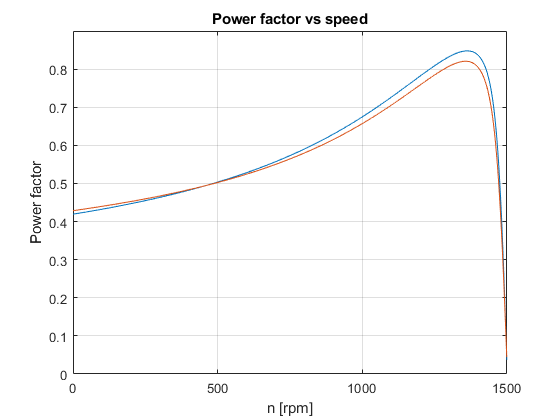


% Plot power factor vs. speed characteristic curves
plot(n,PF_ee),xlabel('n [rpm]'),ylabel('Power factor'),...
    title('Power factor vs speed'),grid on,...
    hold on
plot(n,abs(PF_se))

hold off

% (a) Power factors at startup

% (b) Power factors when the machines develop maximum torque

% (c) Power factor when the machines are operating under no-load conditions

% (d) Determine the best power factors that these machines can operate at

% (e) Determine the speeds (in rpm) at which the best power factors occur

% 5. Plot total input power,
%               stator copper losses,
%               air gap power,
%               rotor copper losses and
%               shaft power
%                               vs speed, on the same set of axis
% *Rotational losses of machines are negligable
% *Seperate plots for each machine

disp('5. Power and losses plots of machines');

5. Power and losses plots of machines


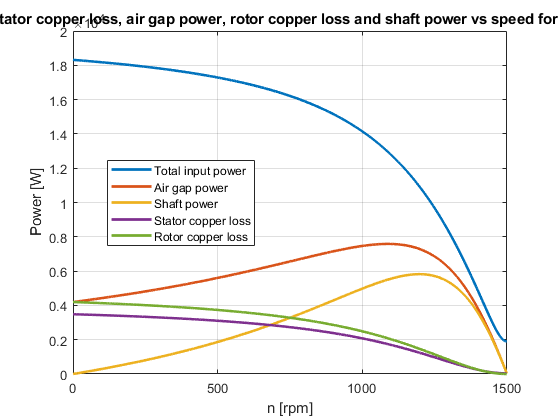


% EE motor
I2p_ee = Vth_ee./(Rth_ee+R2p_ee./s+1i*(Xth_ee+X2p_ee));      % Rotor current referred to primary

P1cu_ee = 3*I1_ee.^2*R1_ee;         % stator copper loss
Pag_ee = 3*I2p_ee.^2*R2p_ee./s;     % air gap power
P2cu_ee = 3*I2p_ee.^2*R2p_ee;       % rotor copper loss
Pshaft_ee = (1-s).*Pag_ee;          % shaft power Pshaft = Pmech since Prot is negligable
%Pin_ee = Pshaft_ee+P1cu_ee+P2cu_ee;            % total input power = Pag + P1cu
Pin_ee = 3*V1*I1_ee;

% generate plots of powers and losses
plot(n,abs(Pin_ee),n,abs(Pag_ee),n,abs(Pshaft_ee),n,abs(P1cu_ee),n,abs(P2cu_ee),'linewidth',2),xlabel('n [rpm]'),ylabel('Power [W]'),...
    title('Total input power, stator copper loss, air gap power, rotor copper loss and shaft power vs speed for Energy Efficient motor'),grid on,...
legend({'Total input power','Air gap power','Shaft power','Stator copper loss','Rotor copper loss'},'Location','best');

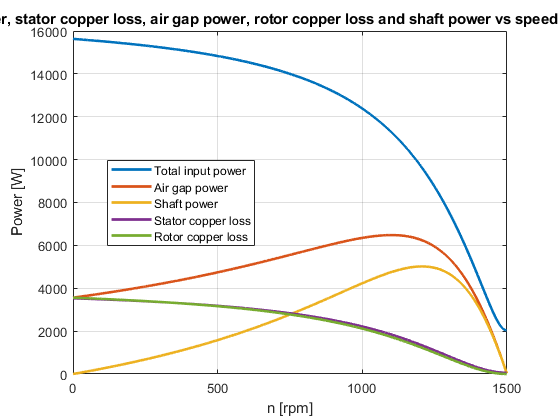



% SE motor
I2p_se = Vth_se./(Rth_se+R2p_se./s+1i*(Xth_se+X2p_se));      % Rotor current referred to primary

P1cu_se = 3*I1_se.^2*R1_se;         % stator copper loss
Pag_se = 3*I2p_se.^2*R2p_se./s;     % air gap power
P2cu_se = 3*I2p_se.^2*R2p_se;       % rotor copper loss
Pshaft_se = (1-s).*Pag_se;          % shaft power Pshaft = Pmech since Prot is negligable
%Pin_se = Pag_se+P1cu_se;            % total input power = Pag + P1cu
Pin_se = 3*V1*I1_se;

% generate plots of powers and losses
plot(n,abs(Pin_se),n,abs(Pag_se),n,abs(Pshaft_se),n,abs(P1cu_se),n,abs(P2cu_se),'linewidth',2),xlabel('n [rpm]'),ylabel('Power [W]'),...
    title('Total input power, stator copper loss, air gap power, rotor copper loss and shaft power vs speed for Standard motor'),grid on,...
legend({'Total input power','Air gap power','Shaft power','Stator copper loss','Rotor copper loss'},'Location','best');

% 5. (a) Stator and rotor copper losses at start up
disp('(a) Stator and rotor copper losses at start up');

(a) Stator and rotor copper losses at start up



% EE motor
fprintf('Stator copper loss of Energy Efficient motor at startup = %f W',abs(P1cu_ee(2000)));

Stator copper loss of Energy Efficient motor at startup = 3485.259326 W

fprintf('Rotor copper loss of Energy Efficient motor at startup = %f W',abs(P2cu_ee(2000)));

Rotor copper loss of Energy Efficient motor at startup = 4196.180537 W


% SE motor
fprintf('Stator copper loss of Standard motor at startup = %f W',abs(P1cu_se(2000)));

Stator copper loss of Standard motor at startup = 3531.634309 W

fprintf('Rotor copper loss of Standard motor at startup = %f W',abs(P2cu_se(2000)));

Rotor copper loss of Standard motor at startup = 3560.428357 W

% 5. (b) Stator and rotor copper losses under no-load conditions
disp('(b) Stator and rotor copper losses under no-load conditions');

% EE motor
fprintf('Stator copper loss of Energy Efficient motor under no-load conditions = %f W',abs(P1cu_ee(1)));
fprintf('Rotor copper loss of Energy Efficient motor under no-load conditions = %f W',abs(P2cu_ee(1)));

% SE motor
fprintf('Stator copper loss of Standard motor under no-load conditions = %f W',abs(P1cu_se(1)));
fprintf('Rotor copper loss of Standard motor under no-load conditions = %f W',abs(P2cu_se(1)));

% 6. Efficiency vs. speed characteristics
disp('6. Efficiency vs. speed characteristics')

6. Efficiency vs. speed characteristics


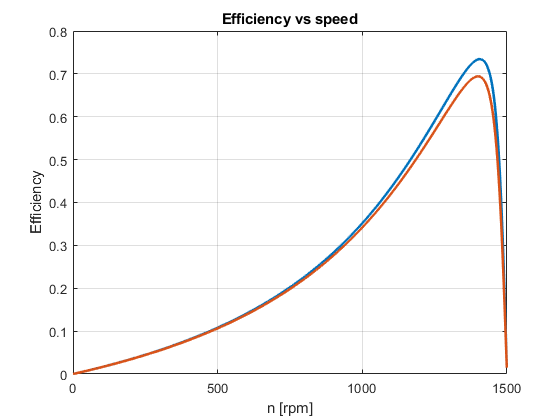


% EE motor
eff_ee = Pshaft_ee./Pin_ee;      % efficiency = Pout/Pin

% SE motor
eff_se = Pshaft_se./Pin_se;      % efficiency = Pout/Pin

% Plot the characteristics
plot(n,abs(eff_ee),n,abs(eff_se),'linewidth',2),xlabel('n [rpm]'),ylabel('Efficiency'),...
    title('Efficiency vs speed'),grid on,...
    %legend({'EE motor','SE motor'},'Location','best');

% 6. (a) Efficiencies of machines at maximum torque
disp('(a) Efficiencies of the motors at maximum torque')


% 6. (b) Maximum efficiency of machines
disp('(b) Maximum efficiency of machine')

%fprintf('Maximum efficiency of Energy Efficient motor = %f',)